# Maximum Likelihood Decoder for ON DSGCs

How well do spike responses in UP and DOWN ON DSGCs encode stimulus direction?

%Grab Data
downs = grabFromFilter('Downs');
ups = grabFromFilter('Ups');

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'; 'Moving_Grating_Direction'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_ff'; 'SP10'; 'Extracellular'}; %child field name should be one of these. Priority is in given order'
mustHave_1 = [];
mustHave_2 = {'Extracellular'};
cantHave_1 = [];
cantHave_2 = {'Cesium', 'Intracellular', 'Potassium'}; %avoid anything with these tags
rigMandates = []; %no rig mandates

%parse the data to store the responses from every cell for every epoch
%organized by stimulus orientation.
allOrientations = [0:45:315];

upVals = zeros(size(ups, 1), 8); %will hold mean responses of each cell for each stimulus direction
downVals = zeros(size(downs, 1), 8);

upAllSpikesByCell  = cell(8, 2); %will hold # of spikes for all epochs for each cell organized by stimulus orientation
upAllSpikesByCell(:, 1) = num2cell(allOrientations');

downAllSpikesByCell  = cell(8, 2);
downAllSpikesByCell(:, 1) = num2cell(allOrientations');

upAllSpikesByOrientation = cell(8, 1);
downAllSpikesByOrientation = cell(8, 1);



%grab data for up cells
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    
    orientations = loc.Analysis_Results.Orientation;
    spikes = loc.Analysis_Results.mean_spikesByOrientation;
    spikesByOrientation = loc.Analysis_Results.spikesByOrientation;
    
    for j = 1:numel(orientations)
        o_j = orientations(j);
        upVals(i, allOrientations == o_j) = spikes(j);
    end
    upVals(i, :) = upVals(i, :)/max(upVals(i, :)); %normalize
    
    maxFR = 0;
    for j = 1:size(spikesByOrientation, 1)
        rates = spikesByOrientation{j, 2};
        maxFR = max([maxFR, rates]);
    end
    
    for j = 1:numel(orientations)
        slot_j = allOrientations == orientations(j);
        o_j = upAllSpikesByCell{slot_j, 2}; %pull out the cell array inside the cell array that holds total spikes for each epoch for each cell
        normedspikes_j = spikesByOrientation{j, 2}./maxFR;
        o_j{end+1, 1} = normedspikes_j; %insert total spikes for this cell for each epoch at that orientation
        upAllSpikesByCell{slot_j, 2} = o_j; %put o_j back into the bigger cell array
        
        %also store spikes in an array that groups everything together
        %based on orientation but not by cell
        upAllSpikesByOrientation{slot_j} = [upAllSpikesByOrientation{slot_j} normedspikes_j];
    end

end
upMean = mean(upVals); %population tuning curve averaged on a cell by cell basis

%grab data for down cells
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    
    orientations = loc.Analysis_Results.Orientation;
    spikes = loc.Analysis_Results.mean_spikesByOrientation;
    spikesByOrientation = loc.Analysis_Results.spikesByOrientation;

    for j = 1:numel(orientations)
        o_j = orientations(j);
        downVals(i, allOrientations == o_j) = spikes(j);
    end
    downVals(i, :) = downVals(i, :)/max(downVals(i, :));
  
    maxFR = 0;
    for j = 1:size(spikesByOrientation, 1)
        rates = spikesByOrientation{j, 2};
        maxFR = max([maxFR, rates]);
    end
    
    for j = 1:numel(orientations)
        slot_j = allOrientations == orientations(j);
        o_j = downAllSpikesByCell{slot_j, 2}; %pull out the cell array inside the cell array that holds total spikes for each epoch for each cell
        normedspikes_j = spikesByOrientation{j, 2}./maxFR;
        o_j{end+1, 1} = normedspikes_j; %insert total spikes for this cell for each epoch at that orientation
        downAllSpikesByCell{slot_j, 2} = o_j; %put o_j back into the bigger cell array
        
        %also store spikes in an array that groups everything together
        %based on orientation but not by cell
        downAllSpikesByOrientation{slot_j} = [downAllSpikesByOrientation{slot_j} normedspikes_j];
    end
end
downMean = mean(downVals);

upMeanAllTogether = zeros(1, numel(allOrientations));
downMeanAllTogether = zeros(1, numel(allOrientations));
for i = 1:numel(allOrientations)
    upMeanAllTogether(i) = mean(upAllSpikesByOrientation{i});
    downMeanAllTogether(i) = mean(downAllSpikesByOrientation{i});
end

## Response Models

    Decoding models will be built on simulated ON DS responses. In order to simulate the responses of UP and DOWN cells to any given stimulus, I first build distributions that describe the probability of each cell type to produce a certain spike response, given a stimulus. Specifically, I am using a smooth kernel method to fit response distributions of UP and DOWN cells to a bar moving in each of 8 directions. This provides a description of $p\left(r\left|s\right.\right),\;\;s\in S\left\lbrace 0,45,90,135,180,225,270,315\right\rbrace$. 

    The below plots are the distributions of p(r|s) fit from empirical data. Responses are normalized to the maximum response for each cell. Curve color denotes stimulus angle with darker colors indicating angles that are closer to the preferred direction of the cell. Notice the difference in spread between UP and DOWN cell CDF curves across angles - this is a function of the different tuning widths of UP and DOWN cells.

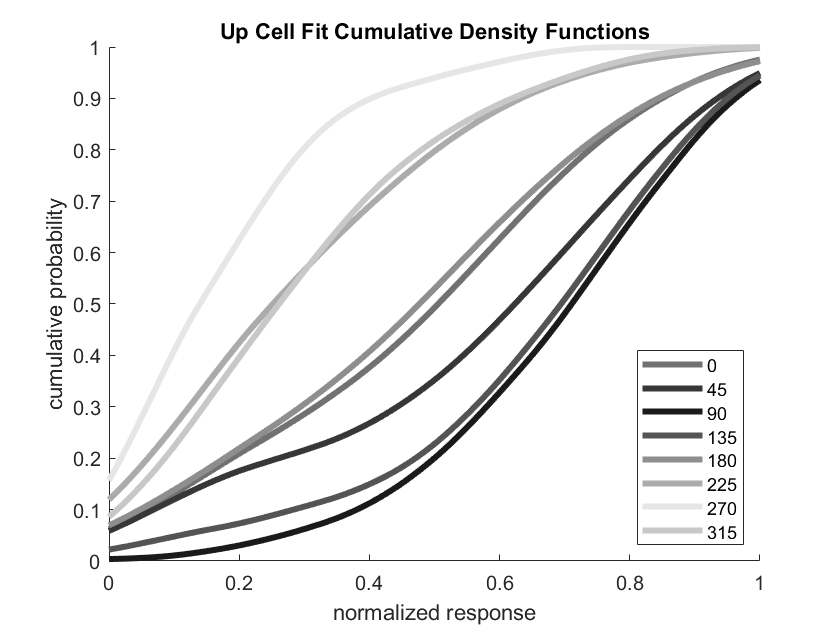

upCDFs = zeros(8, 100); %will hold the fitted values of a cdf for each of 8 stimulus directions for up cells
downCDFs = zeros(8, 100);
xFills = linspace(0, 1, 100);
for i = 1:numel(allOrientations)
    distribution_iUp = upAllSpikesByOrientation{i};
    pd = fitdist(distribution_iUp','Kernel','Kernel','epanechnikov');
    y = cdf(pd, xFills);
    upCDFs(i, :)= y;
    
    distribution_iDown = downAllSpikesByOrientation{i};
    pd = fitdist(distribution_iDown','Kernel','Kernel', 'epanechnikov');
    y = cdf(pd, xFills);
    downCDFs(i, :)= y;
end

colorWeights = linspace(0.1, 0.9, 8)';
colors = repmat(colorWeights, 1, 3);

colorsB = colors([ 4,2,1,3,5 ,6 ,8 ,7], :);
figure
title('Up Cell Fit Cumulative Density Functions')
hold on
plot(xFills, upCDFs, 'LineWidth', 3)
lgd = legend('0', '45', '90', '135', '180', '225', '270', '315');
lgd.Location = 'southeast';
xlabel('normalized response')
ylabel('cumulative probability')
colororder(colorsB)
hold off

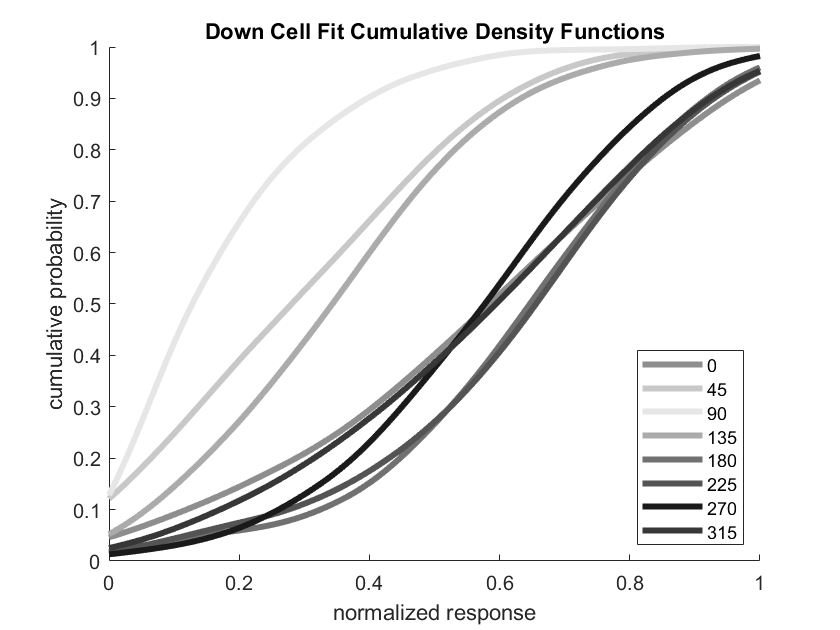

colorsM = colors([ 5,7,8,6,4 ,3 ,1 ,2], :);
%colorsM = repmat([1 0 1], 8, 1).*colorsM;

figure
title('Down Cell Fit Cumulative Density Functions')
hold on
plot(xFills, downCDFs, 'LineWidth', 3)
lgd = legend('0', '45', '90', '135', '180', '225', '270', '315');
lgd.Location = 'southeast';
xlabel('normalized response')
ylabel('cumulative probability')
colororder(colorsM)
hold off

## Simulating Spike Responses

The CDFs can be used to simulate spike responses to each of the 8 stimuli. To do so, one follows these steps: 1) Draw randomly from a uniform distribution of numbers between 0 and 1, 2) Find the location of the randomly drawn number along the on the Y axis of the CDF plot, 3) Locate the X-coordinate at which the selected Y-value meets the CDF curve for the stimulus of interest. Repeate this process to simulate responses to multiple presentations of the same stimulus. 

I validate this technique, and the fit of the above probability distributions, by generating 100 simulated responses to each of the 8 stimuli and comparing them to the empirical mean.

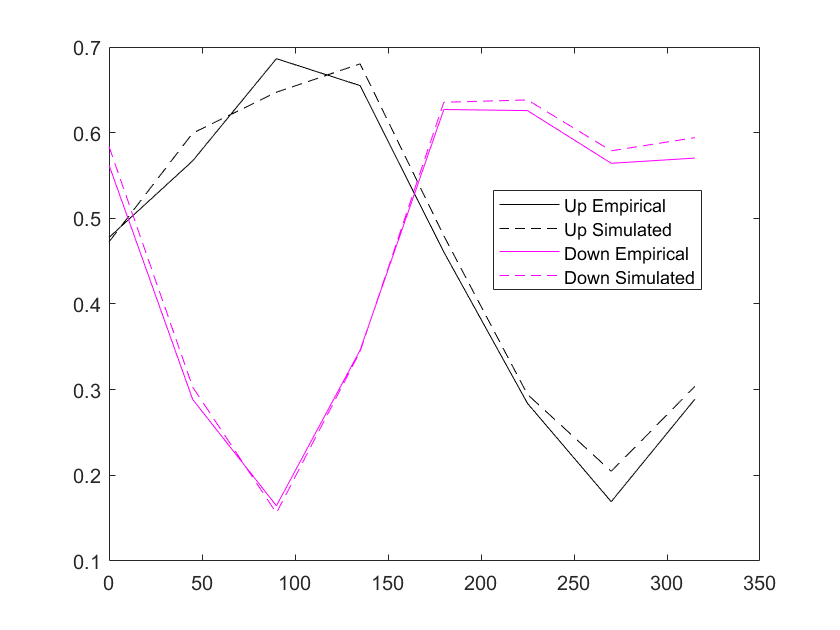

numResponses = 100;
upValidation = zeros(numResponses, numel(allOrientations));
downValidation = upValidation;
for i = 1:numel(allOrientations)
    upValidation(:, i) = randNumSpikesGenerator(upCDFs(i, :), numResponses);
    downValidation(:, i) = randNumSpikesGenerator(downCDFs(i, :), numResponses);
end

n = randNumSpikesGenerator(upCDFs(3, :), numResponses);

figure
plot(allOrientations, upMeanAllTogether, '-k')
hold on
plot(allOrientations, mean(upValidation), '--k')
plot(allOrientations, downMeanAllTogether, '-m')
plot(allOrientations, mean(downValidation), '--m')
lgd = legend('Up Empirical', 'Up Simulated', 'Down Empirical', 'Down Simulated');
lgd.Location = 'best';

## Maximum Likelihood Decoder

Now that we can randomly simulate responses of UP and DOWN cells given a stimulus, we can use this approach to ask how well we can predict a stimulus, given a simulated response. The maximum likelihood decorder (MLD) is one tool that can be used to help answer this question. The MLD maps a spike response to a stimulus by maximizing $L\left(r\left|s\right.\right)$ where $r=\left(c_1 {,\;c}_2 ,\ldotp \ldotp \ldotp ,c_i \right)$. Where $c_1 {,\;c}_2 ,\ldotp \ldotp \ldotp ,c_i$ are the responses of individual cells. For our case, we'll begin by using $L\left(r\left|s\right.\right)=P\left(U_r \left|S\right.\right)P\left(D_r \left|S\right.\right)$, where  $U_r$ is the response of pne UP cell and$\;D_r$is the response of one DOWN cell. Later, we can include responses from additional cells.

To carry out this model, I use the following procedure: 1) Choose a stimulus, 2) Generate random responses to that stimulus using the CDFs for UP and DOWN cells, 3) Ask what the probability is that the stimulated responses were driven by each of the 8 possible stimuli, 4) Predict the stimulus by choosing the option that has the highest probability of having produced the response. To assess the performance of the MLD, I use a few metrics: *MLD error* is calculated in degrees as $\textrm{mean}\left(\left|S-\hat{\;S\;\left|\right.} \right.\right)$. This is the relavent error if a pair of cells encodes stimulis direction. *MLD vertical component error* is $\textrm{mean}\left(\sin \left(S\right)-\sin \left(\hat{S} \right)\right)$. This is the relevant error if a pair of cells encodes the vertical component of any moving stimulus. *MLD accuracy* is the total number of responses that the MLD correctly classified. The *confusion matrix *provides a graphical summary of performance.

%% Maximum Likelihood Decoder
runsPerStimulus = 10000; %runs
upCDFs_FLIPPED = upCDFs([5:8, 1:4], :);
downCDFs_FLIPPED = downCDFs([5:8, 1:4], :);

OriginalDataMLD = MLD(allOrientations, {upCDFs, downCDFs}, runsPerStimulus);
FlippedUpMLD = MLD(allOrientations, {upCDFs, upCDFs_FLIPPED}, runsPerStimulus);
FlippedDownMLD = MLD(allOrientations,{downCDFs_FLIPPED, downCDFs}, runsPerStimulus);

disp(['MLD Accuracy - Asymmetric: ' num2str(OriginalDataMLD.accuracy) newline...
    'MLD Accuracy - Flipped UP: ' num2str(FlippedDownMLD.accuracy) newline...
    'MLD Accuracy - Flipped Down: ' num2str(FlippedUpMLD.accuracy)]);

MLD Accuracy - Asymmetric: 0.31827
MLD Accuracy - Flipped UP: 0.32748
MLD Accuracy - Flipped Down: 0.2942


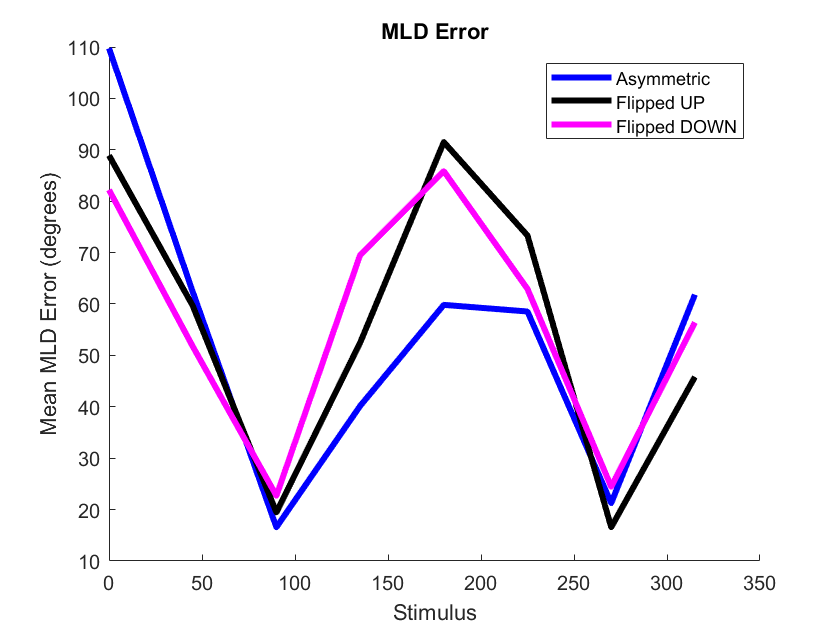

figure
title('MLD Error')
hold on
plot(allOrientations, OriginalDataMLD.meanError,  '-b', 'LineWidth', 3)
plot(allOrientations, FlippedUpMLD.meanError, '-k', 'LineWidth', 3)
plot(allOrientations, FlippedDownMLD.meanError, '-m', 'LineWidth', 3)
xlabel('Stimulus')
ylabel('Mean MLD Error (degrees)')
legend('Asymmetric', 'Flipped UP', 'Flipped DOWN')
hold off

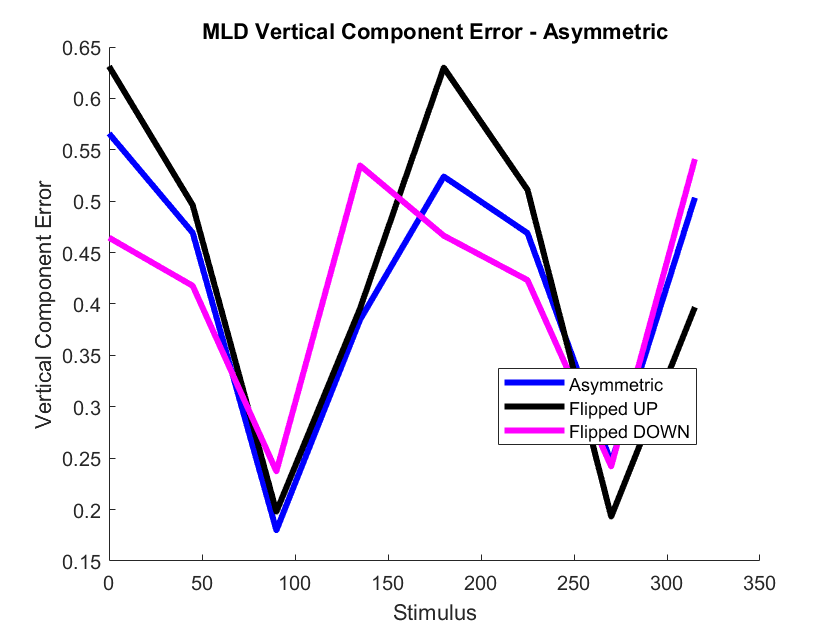

figure
title('MLD Vertical Component Error - Asymmetric')
hold on
plot(allOrientations, OriginalDataMLD.meanVerticalComponentError, '-b', 'LineWidth', 3)
plot(allOrientations, FlippedUpMLD.meanVerticalComponentError, '-k', 'LineWidth', 3)
plot(allOrientations, FlippedDownMLD.meanVerticalComponentError, '-m', 'LineWidth', 3)
lgd = legend('Asymmetric', 'Flipped UP', 'Flipped DOWN');
lgd.Location = 'best';
xlabel('Stimulus')
ylabel('Vertical Component Error')

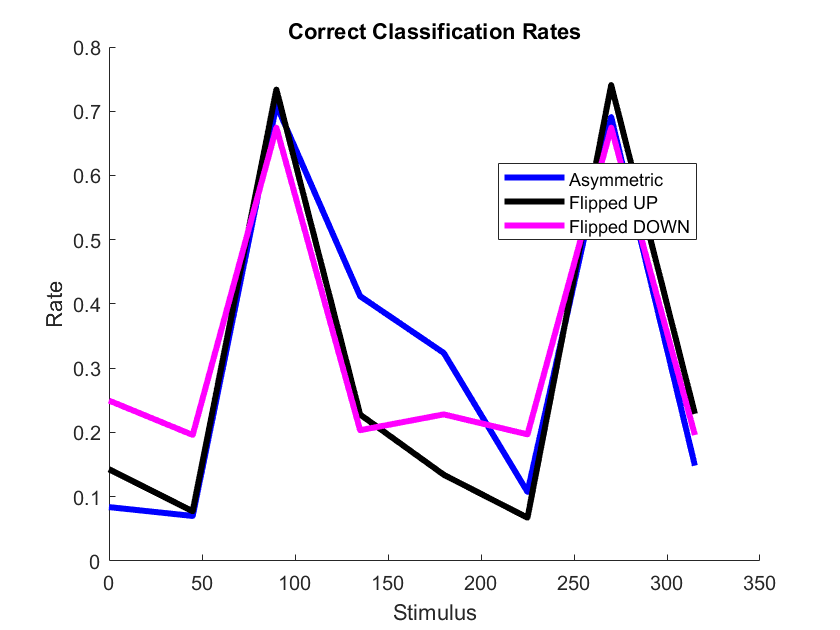

figure
title('Correct Classification Rates')
hold on
plot(allOrientations, OriginalDataMLD.trueHitRate, 'b',  'LineWidth', 3)
plot(allOrientations, FlippedUpMLD.trueHitRate, 'k', 'LineWidth', 3)
plot(allOrientations, FlippedDownMLD.trueHitRate, 'm', 'LineWidth', 3)
ylabel('Rate')
xlabel('Stimulus')
lgd = legend('Asymmetric', 'Flipped UP', 'Flipped DOWN');
lgd.Location = 'best';

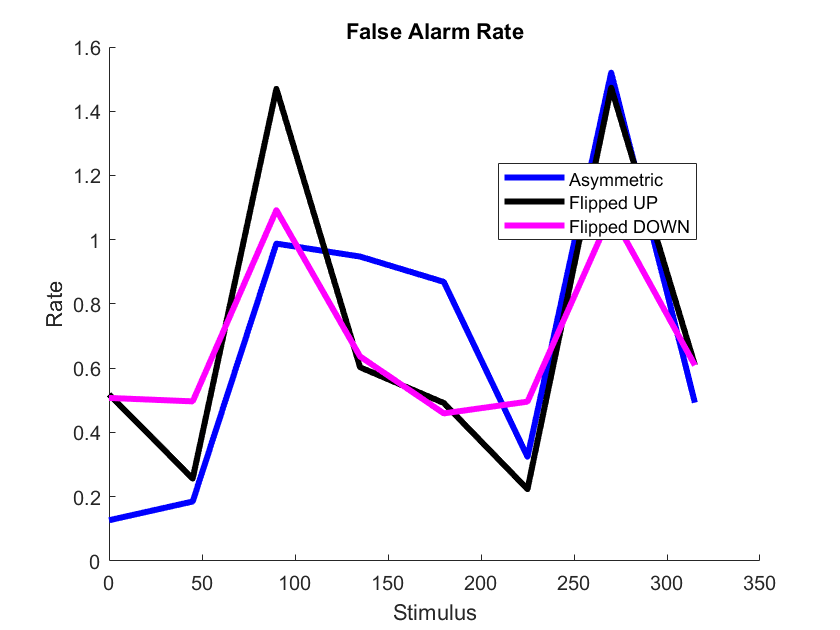

figure
title('False Alarm Rate')
hold on
plot(allOrientations, OriginalDataMLD.falseAlarmRate, 'b',  'LineWidth', 3)
plot(allOrientations, FlippedUpMLD.falseAlarmRate, 'k', 'LineWidth', 3)
plot(allOrientations, FlippedDownMLD.falseAlarmRate, 'm', 'LineWidth', 3)
ylabel('Rate')
xlabel('Stimulus')
lgd = legend('Asymmetric', 'Flipped UP', 'Flipped DOWN');
lgd.Location = 'best';

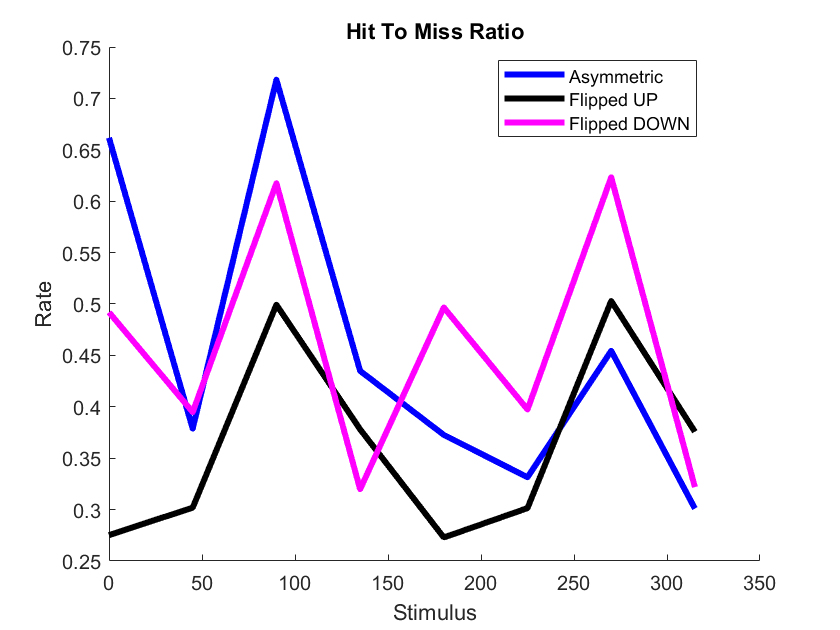

figure
title('Hit To Miss Ratio')
hold on
plot(allOrientations, OriginalDataMLD.hitToMissRatio, 'b',  'LineWidth', 3)
plot(allOrientations, FlippedUpMLD.hitToMissRatio, 'k', 'LineWidth', 3)
plot(allOrientations, FlippedDownMLD.hitToMissRatio, 'm', 'LineWidth', 3)
ylabel('Rate')
xlabel('Stimulus')
lgd = legend('Asymmetric', 'Flipped UP', 'Flipped DOWN');
lgd.Location = 'best';

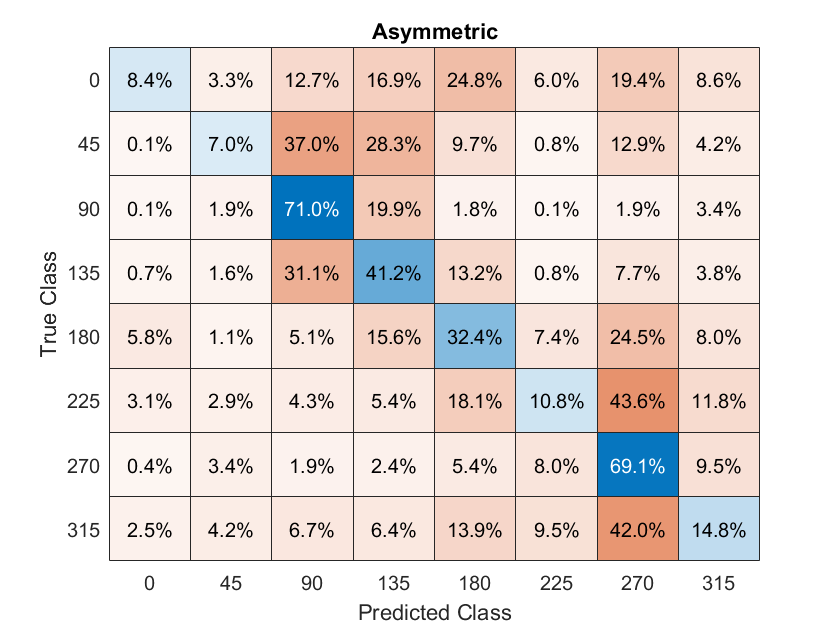

figure    
cm = confusionchart(OriginalDataMLD.trueStims, OriginalDataMLD.predictedStims);
cm.Normalization = 'row-normalized';
title('Asymmetric')

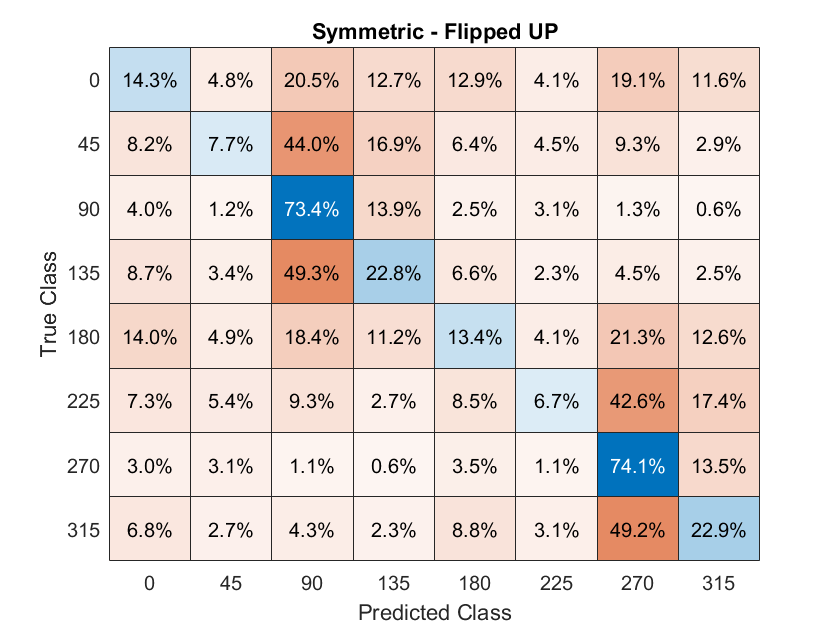

figure    
cm = confusionchart(FlippedUpMLD.trueStims, FlippedUpMLD.predictedStims);
cm.Normalization = 'row-normalized';
title('Symmetric - Flipped UP')

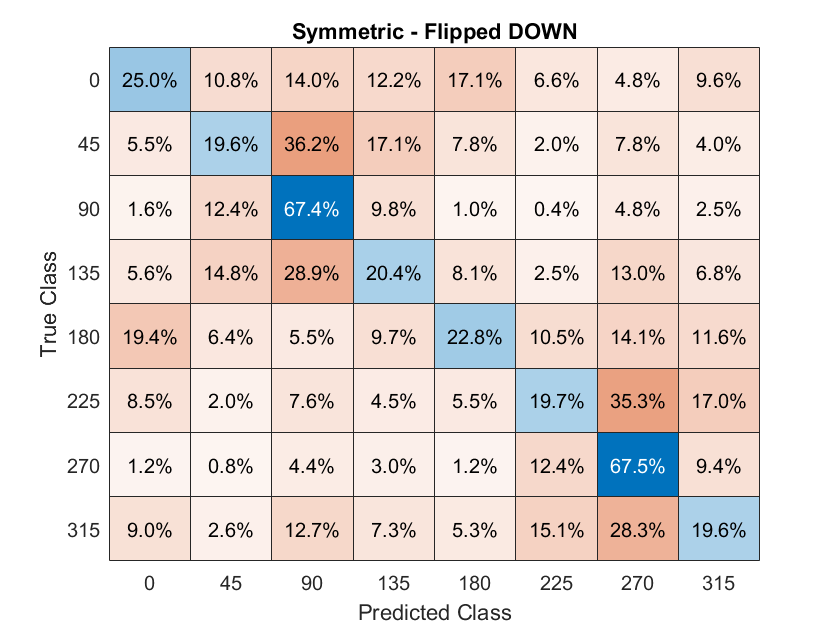

figure    
cm = confusionchart(FlippedDownMLD.trueStims, FlippedDownMLD.predictedStims);
cm.Normalization = 'row-normalized';
title('Symmetric - Flipped DOWN')

### Comparison To Other Decoders

Machine learning classifiers are another possible solution to decoding ON DSGC activity. Below I compare the performance of a variety of trained classifiers to decode stimulus direction from simulated ON DSGC responses.

load('C:\Users\mrsco\Box\Completed_Analysis\20210525\trainedModels\twoCells\trainedModelKNN.mat')
load('C:\Users\mrsco\Box\Completed_Analysis\20210525\trainedModels\twoCells\trainedModelNaiveBayes.mat')
load('C:\Users\mrsco\Box\Completed_Analysis\20210525\trainedModels\twoCells\trainedModelTree.mat')
load('C:\Users\mrsco\Box\Completed_Analysis\20210525\trainedModels\twoCells\trainedModelSVM.mat')

trainingData = generateTrainingData(allOrientations, 1000, {upCDFs, downCDFs});

validationData = trainingData(:, [1 2]);
trueClassifications = trainingData(:, 3);

KNNpredictions = trainedModelKNN.predictFcn(validationData);
KNNaccuracy = sum(KNNpredictions == trueClassifications)/numel(KNNpredictions);

NaiveBayesPredictions = trainedModelNaiveBayes.predictFcn(validationData);
NaiveBayesAccuracy = sum(NaiveBayesPredictions == trueClassifications)/numel(NaiveBayesPredictions);

treePredictions = trainedModelTree.predictFcn(validationData);
treeAccuracy = sum(treePredictions == trueClassifications)/numel(treePredictions);

SVMpredictions = trainedModelSVM.predictFcn(validationData);
SVMaccuracy = sum(SVMpredictions == trueClassifications)/numel(SVMpredictions);

disp(['KNN Accuracy: ' num2str(KNNaccuracy) newline...
    'Naive Bayes Accuracy: ' num2str(NaiveBayesAccuracy) newline...
    'Decision Tree Accuracy: ' num2str(treeAccuracy) newline...
    'Support Vector Machine Accuracy: ' num2str(SVMaccuracy)]);

KNN Accuracy: 0.29563
Naive Bayes Accuracy: 0.30625
Decision Tree Accuracy: 0.29838
Support Vector Machine Accuracy: 0.30675


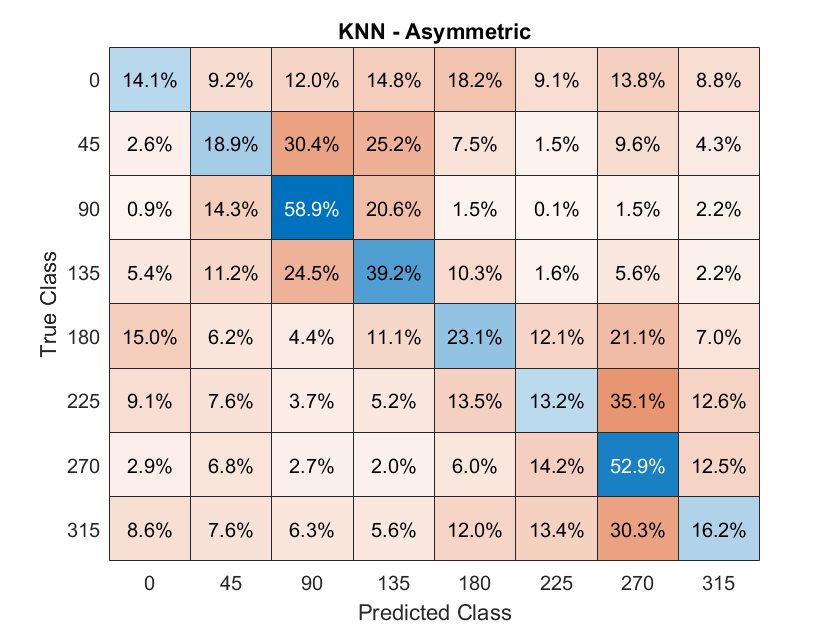

figure    
cm = confusionchart(trueClassifications, KNNpredictions);
cm.Normalization = 'row-normalized';
title('KNN - Asymmetric')

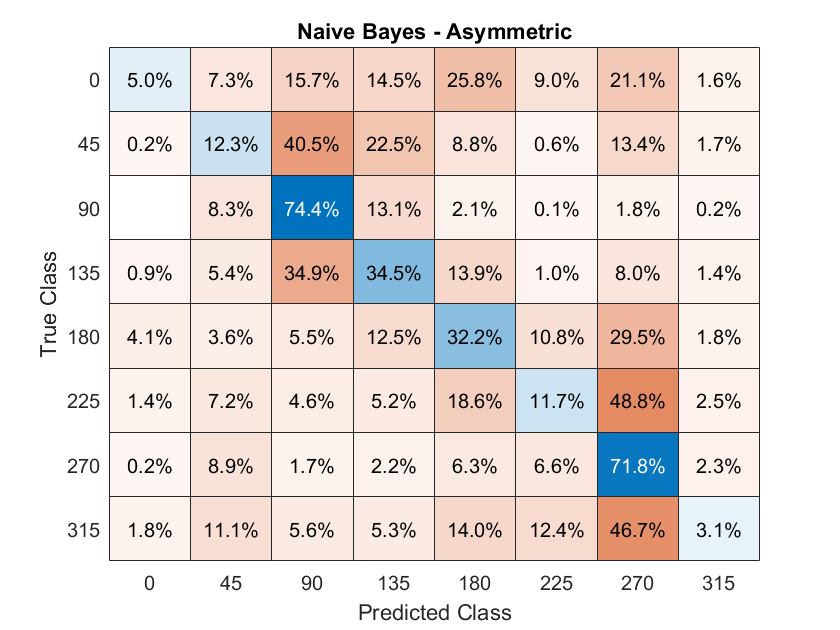

figure    
cm = confusionchart(trueClassifications, NaiveBayesPredictions);
cm.Normalization = 'row-normalized';
title('Naive Bayes - Asymmetric')

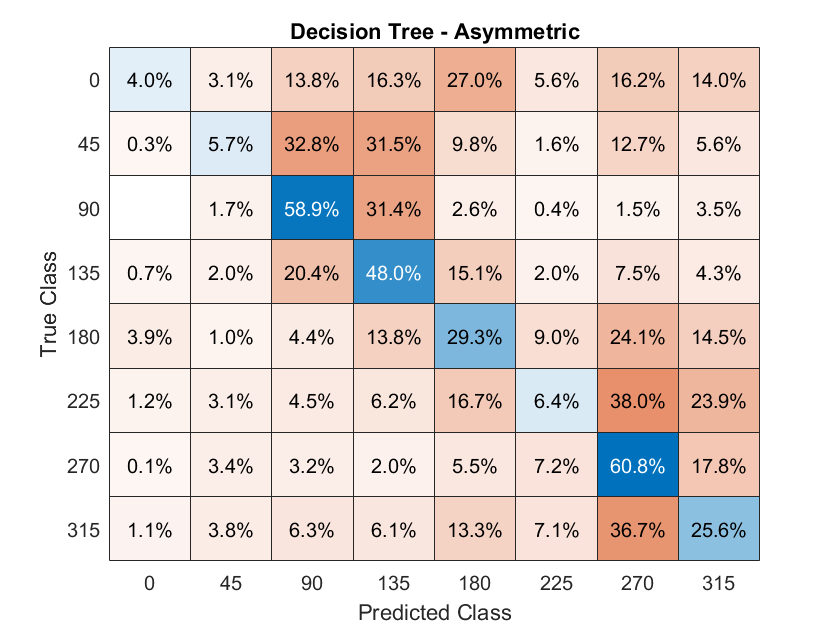

figure    
cm = confusionchart(trueClassifications, treePredictions);
cm.Normalization = 'row-normalized';
title('Decision Tree - Asymmetric')

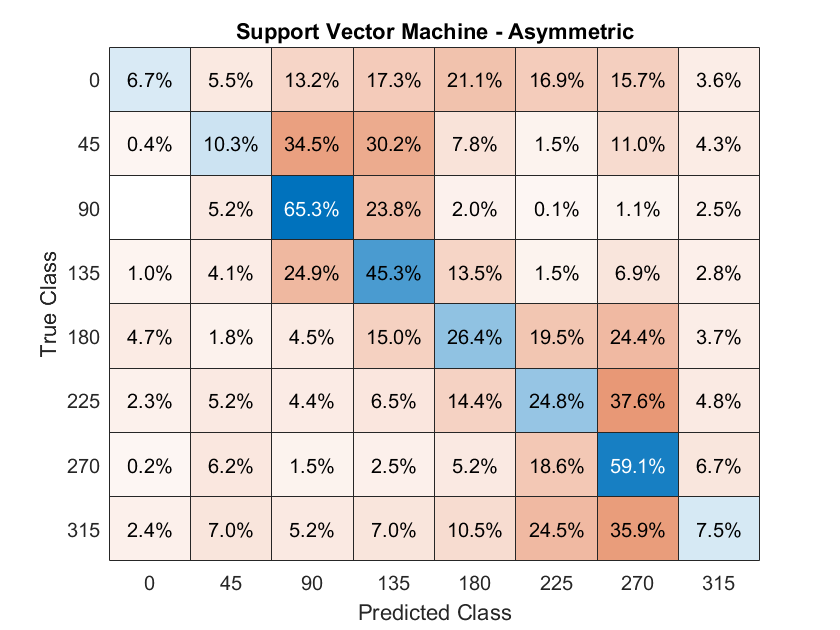

figure    
cm = confusionchart(trueClassifications, SVMpredictions);
cm.Normalization = 'row-normalized';
title('Support Vector Machine - Asymmetric')

None of the trained classifiers outperforms the MLD. Further, they each recapitulate the tendency of the MLD to over categorize responses as 90 and 270 degrees. Because there does not appear to be much of a difference between the MLD and the trained models, the remainder of this analysis will use only the MLD for all decoding tasks.

## Convergence

The above models attempt to decode direction given simulated the responses of one UP and one DOWN cell. In this section, I will examine the effects of increasing the number of UP and DOWN cells that the decoder has access to.

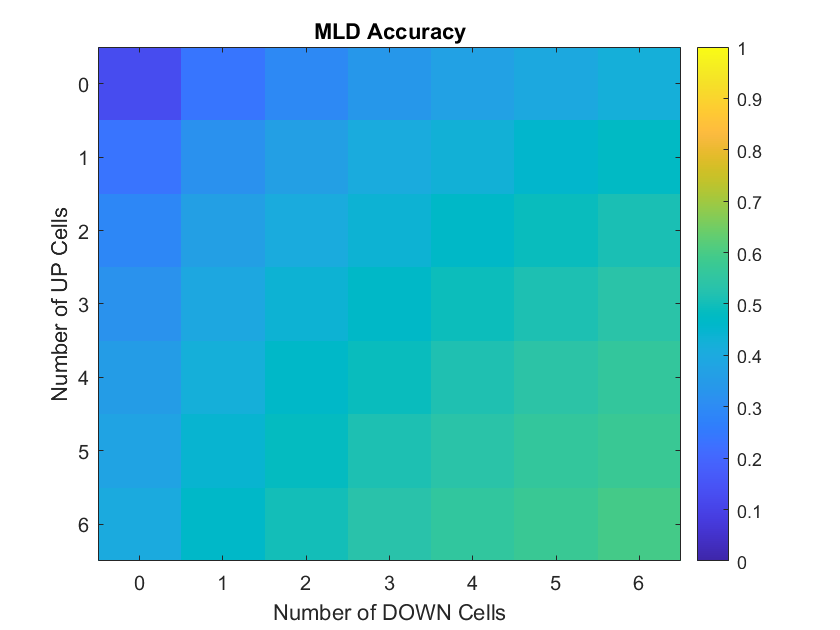

numberOfUpCells = 0:6;
numberOfDownCells = 0:6;

convergenceAccuracyMatrix = zeros(numel(numberOfUpCells), numel(numberOfDownCells));

for u = numberOfUpCells
    for d = numberOfDownCells
        
        if u == 0 && d == 0 %Calculate random chance classification for 0 up and 0 down cells
            convergenceAccuracyMatrix(1, 1) = sum(randi(numel(allOrientations),...
                runsPerStimulus, 1) == randi(numel(allOrientations),...
                runsPerStimulus, 1))/runsPerStimulus; % random chance (should converge to 1/number of stimuli)
            continue
        end
        
        cdfArray = cell(1, u + d);
        cdfArray(1:u) = {upCDFs};
        cdfArray(u+1:d+u) = {downCDFs};
        classifications_ud = MLD(allOrientations, cdfArray, runsPerStimulus);
        
        convergenceAccuracyMatrix(u+1, d+1) = classifications_ud.accuracy;
    end
end

figure
imagesc(convergenceAccuracyMatrix)
hold on
title('MLD Accuracy')
ts = {'0', '1', '2', '3', '4', '5', '6'};
xticklabels(ts)
yticklabels(ts)
xlabel('Number of DOWN Cells')
ylabel('Number of UP Cells')
colorbar
caxis([0 1])

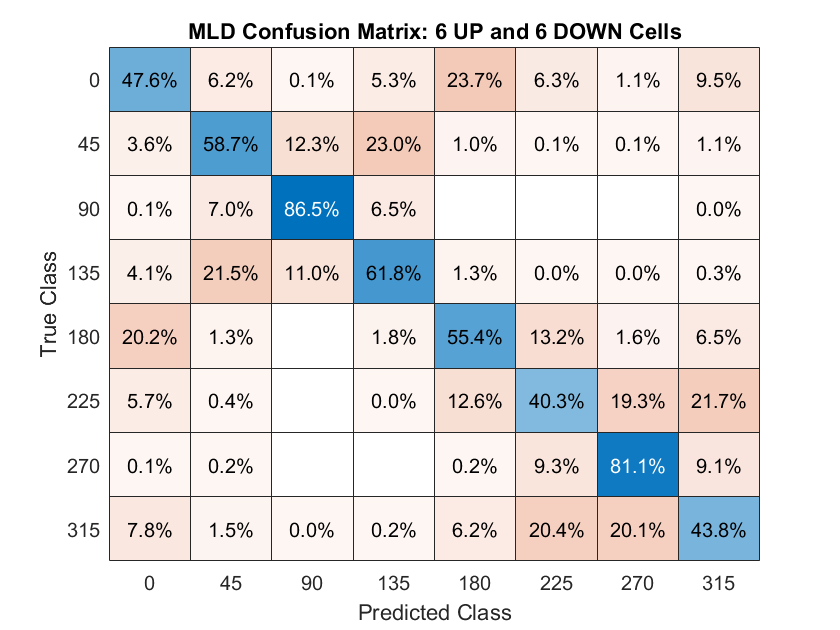

figure
cm = confusionchart(classifications_ud.trueStims, classifications_ud.predictedStims);
cm.Normalization = 'row-normalized';
title('MLD Confusion Matrix: 6 UP and 6 DOWN Cells')

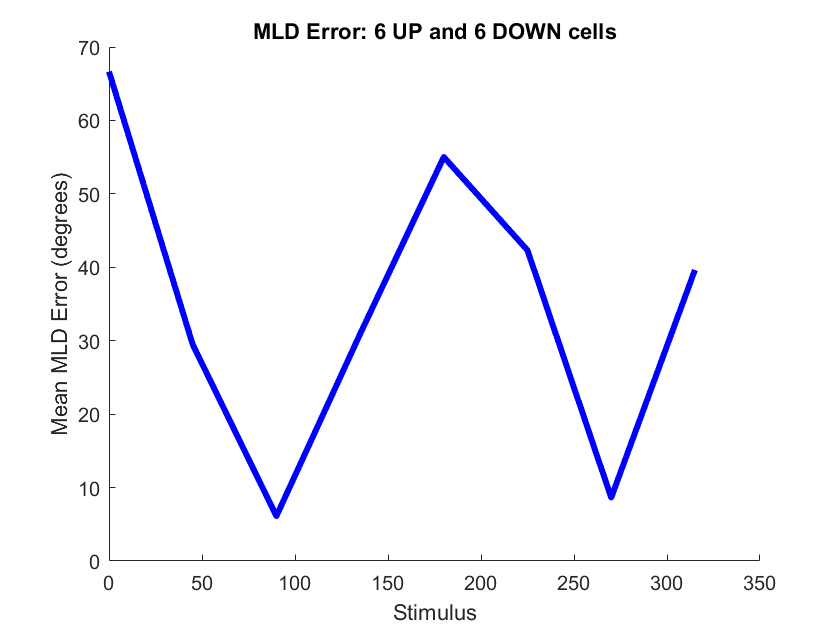

figure
title('MLD Error: 6 UP and 6 DOWN cells')
hold on
plot(allOrientations, classifications_ud.meanError,  '-b', 'LineWidth', 3)
xlabel('Stimulus')
ylabel('Mean MLD Error (degrees)')
hold off

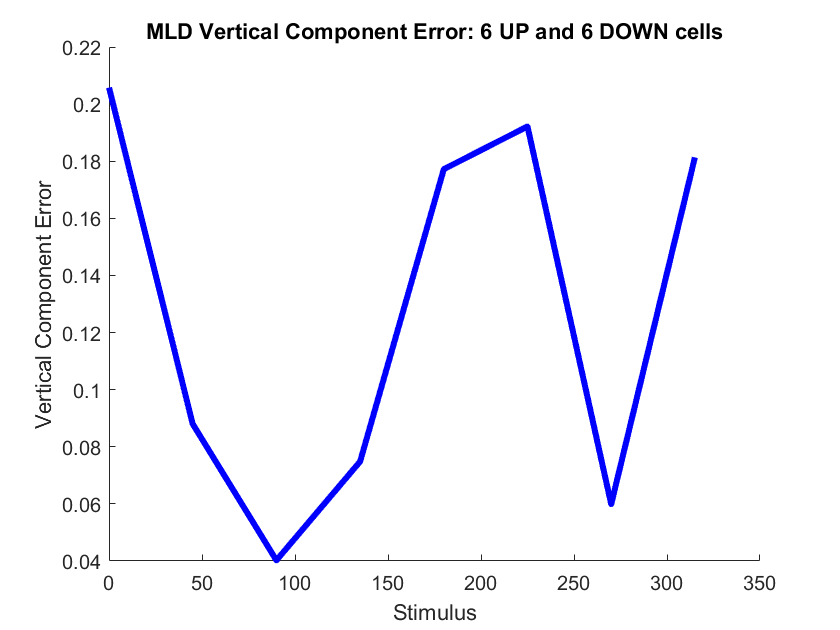


figure
title('MLD Vertical Component Error: 6 UP and 6 DOWN cells')
hold on
plot(allOrientations, classifications_ud.meanVerticalComponentError, '-b', 'LineWidth', 3)
xlabel('Stimulus')
ylabel('Vertical Component Error')

Conversion improves decoding. It does not, however, yield 100% accuracy in the range explored. 

## Correlated Noise

Noise correlations across cells may also affect decoding performance.

## Bayesian Decoding

Subtracting the firing rate of one cell from the other is one possible of encoding stimuli, but it is not the only possibility. Therefore, it would be nice to be able to state how well different directions are encoded while remaining agnostic about particular encoding and decoding schemes. The goal is to build a model for which we can input a stimulus and predict which response produced that stimulus. Then, we'll compare the ability of a symmetric and asymmetric model to decode stimuli given any arbitrary response.

The CDFs provide the probability of a response given a stimulus $P\left(R\left|S\right.\right)$. To decode, we need to calculate $P\left(S\left|R\right.\right)$. These two probabilities can be related to each other using Baye's rule $P\left(S\left|R\right.\right)=\frac{P\left(R\left|S\right.\right)P\left(S\right)}{P\left(R\right)}$. In the subtraction model, we used the shortcut of $R=\textrm{UP}\;\textrm{response}-\textrm{DOWN}\;\textrm{response}\;$, which reduced the dimensionality of the problem. To be more general, however, we will now use $R=\left(\textrm{UP}\;\textrm{response},\;\textrm{DOWN}\;\textrm{response}\right)$. Translated to Baye's rule, $P\left(S\left|U_r ,\;D_r \right.\right)=\frac{P\left(U_r ,\;D_r \left|S\right.\right)P\left(S\right)}{P\left(U_r ,\;D_r \right)}$ where $U_r$ is the response of UP cells and$\;D_r$is the response of DOWN cells. If there is no noise correlation between UP and DOWN cells then $U_r$ and $D_r$ are independent and $P\left(U_r ,\;D_r \right)\;=\;P\left(U_r \right)P\left(D_r \right)$. 

To begin, we will remain discrete and say that $P\left(S\right)=\frac{1}{8}$ for all stimuli. Later we can generalize to the continuous case.